rng default % for reproducibility
d = linspace(0,3);
y = exp(-1.3*d) + 0.05*randn(size(d));

fun = @(r)exp(-d*r)-y;

x0 = 4;
x = lsqnonlin(fun,x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x = 1.2645

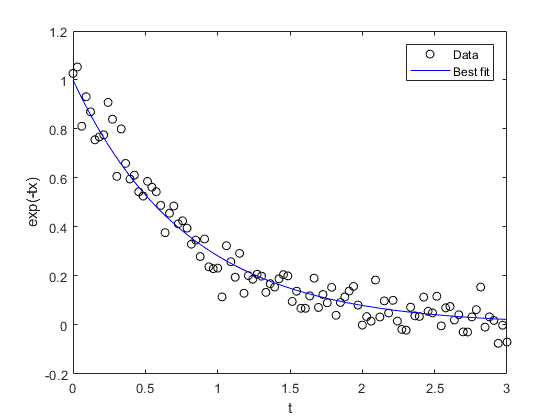


plot(d,y,'ko',d,exp(-x*d),'b-');
legend('Data','Best fit');
xlabel('t');
ylabel('exp(-tx)');

% rng default % for reproducibility
d = linspace(0,3,1000);
b=0.05;
y = exp(-1.4*d)+b;
y=awgn(y,10,'measured');

fun = @(r)exp(-d*r(1))+r(2)-y;

x0 = [1.45 5];
x = lsqnonlin(fun,x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =     1.4255    0.0495



plot(d,y,'ko',d,exp(-x(1)*d)+x(2),'b-');
legend('Data','Best fit');

$\sqrt{\beta }+\sqrt[3]{r}$+3

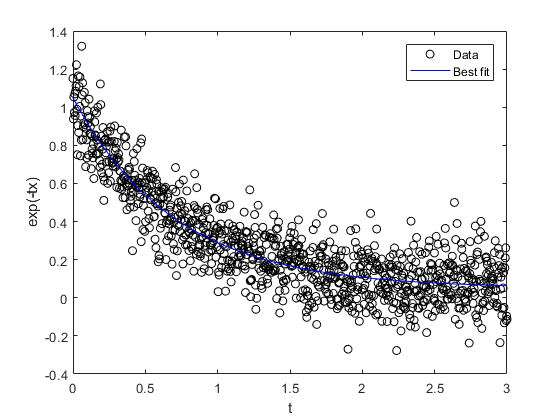

xlabel('t');
ylabel('exp(-tx)');